clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[4.509;6.720;9.828];
u31=[0.351;0.531;0.771];
r2=[-0.881;6.308;1.211];
u32=[-0.351;-0.531;0.771];
r3=[6.376;6.308;1.211];
u33=[-0.351;-0.531;0.771];
r4=[0.881;12.822;7.407];
u34=[0.351;-0.531;-0.771];
r5=[8.137;12.822;7.407];
u35=[0.351;-0.531;-0.771];
r6=[-0.881;6.308;18.445];
u36=[-0.351;-0.531;0.771];
r7=[6.376;6.308;18.445];
u37=[-0.351;-0.531;0.771];
r8=[2.748;0.206;16.024];
u38=[-0.351;0.531;-0.771];
r9=[10.004;0.206;16.024];
u39=[-0.351;0.531;-0.771];
r10=[11.765;6.720;9.828];
u310=[0.351;0.531;0.771];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];

hold on 
axis([0 15 0 15]);

for R1=3:0.3:8 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     3.0000    8.6000    1.0001


ans =     3.3000    7.7200    1.0006


ans =     3.6000    7.0900    1.0000


ans =     3.9000    6.5800    1.0006


ans =     4.2000    6.1500    1.0005


ans =     4.5000    5.7600    1.0016


ans =     4.8000    5.4100    1.0005


ans =     5.1000    5.0700    1.0001


ans =     5.4000    4.7300    1.0005


ans =     5.7000    4.3900    1.0002


ans =     6.0000    4.0400    1.0000


ans =     6.3000    3.6700    1.0008


ans =     6.6000    3.2900    1.0003


ans =     6.9000    2.8800    1.0015


ans =     7.2000    2.4600    1.0016


ans =     7.5000    2.0300    1.0012


ans =     7.8000    1.5900    1.0014


plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R1=2:0.3:7 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     2.0000    6.0800    1.0005


ans =     2.3000    5.8000    1.0020


ans =     2.6000    5.5800    1.0027


ans =     2.9000    5.3900    1.0021


ans =     3.2000    5.2100    1.0013


ans =     3.5000    5.0300    1.0004


ans =     3.8000    4.8400    1.0004


ans =     4.1000    4.6400    1.0001


ans =     4.4000    4.4200    1.0009


ans =     4.7000    4.1800    1.0015


ans =     5.0000    3.9200    1.0009


ans =     5.3000    3.6300    1.0000


ans =     5.6000    3.2900    1.0013


ans =     5.9000    2.9000    1.0016


ans =     6.2000    2.4400    1.0008


ans =     6.5000    1.8600    1.0006


ans =     6.8000    1.1000    1.0009


plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')


for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans =     3.9300    2.0000    1.0012


ans =     3.8800    2.3000    1.0027


ans =     3.8400    2.6000    1.0038


ans =     3.8100    2.9000    1.0034


ans =     3.7900    3.2000    1.0003


ans =     3.7600    3.5000    1.0038


ans =     3.7400    3.8000    1.0035


ans =     3.7200    4.1000    1.0041


ans =     3.7100    4.4000    1.0002


ans =     3.6900    4.7000    1.0019


ans =     3.6700    5.0000    1.0040


ans =     3.6600    5.3000    1.0013


ans =     3.6400    5.6000    1.0039


ans =     3.6300    5.9000    1.0016


ans =     3.6100    6.2000    1.0047


ans =     3.6000    6.5000    1.0028


ans = 1×3
    3.5900    6.8000    1.0010


ans = 1×3
    3.5700    7.1000    1.0046


ans = 1×3
    3.5600    7.4000    1.0032


ans = 1×3
    3.5500    7.7000    1.0020


ans = 1×3
    3.5400    8.0000    1.0010


ans = 1×3
    3.5300    8.3000    1.0001


ans = 1×3
    3.5100    8.6000    1.0047


ans = 1×3
    3.5000    8.9000    1.0042


ans = 1×3
    3.4900    9.2000    1.0039


ans = 1×3
    3.4800    9.5000    1.0038


ans = 1×3
    3.4700    9.8000    1.0038


ans = 1×3
    3.4600   10.1000    1.0041


ans = 1×3
    3.4500   10.4000    1.0045


ans = 1×3
    3.4400   10.7000    1.0051


ans = 1×3
    3.4400   11.0000    1.0006


ans = 1×3
    3.4300   11.3000    1.0016


ans = 1×3
    3.4200   11.6000    1.0027


ans = 1×3
    3.4100   11.9000    1.0040


ans = 1×3
    3.4100   12.2000    1.0001


ans = 1×3
    3.4000   12.5000    1.0017


ans = 1×3
    3.3900   12.8000    1.0036


plot(x3,y3,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','1-4')


for R3=2:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    6.5300    2.0000    1.0001


ans = 1×3
    6.2400    2.3000    1.0022


ans = 1×3
    5.9700    2.6000    1.0017


ans = 1×3
    5.7100    2.9000    1.0020


ans = 1×3
    5.4700    3.2000    1.0012


ans = 1×3
    5.2400    3.5000    1.0026


ans = 1×3
    5.0400    3.8000    1.0008


ans = 1×3
    4.8500    4.1000    1.0010


ans = 1×3
    4.6700    4.4000    1.0026


ans = 1×3
    4.5100    4.7000    1.0021


ans = 1×3
    4.3600    5.0000    1.0017


ans = 1×3
    4.2200    5.3000    1.0008


ans = 1×3
    4.0800    5.6000    1.0020


ans = 1×3
    3.9500    5.9000    1.0019


ans = 1×3
    3.8300    6.2000    1.0004


ans = 1×3
    3.7100    6.5000    1.0005


ans = 1×3
    3.5900    6.8000    1.0023


ans = 1×3
    3.4800    7.1000    1.0026


ans = 1×3
    3.3800    7.4000    1.0015


ans = 1×3
    3.2800    7.7000    1.0024


ans = 1×3
    3.1900    8.0000    1.0019


ans = 1×3
    3.1100    8.3000    1.0001


ans = 1×3
    3.0300    8.6000    1.0006


ans = 1×3
    2.9500    8.9000    1.0037


ans = 1×3
    2.8900    9.2000    1.0013


ans = 1×3
    2.8300    9.5000    1.0013


ans = 1×3
    2.7700    9.8000    1.0037


plot(x6,y6,'color',[237, 125, 49]/256, ...
    'LineWidth',1.5,'DisplayName','1-8')


for R3=2:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];   
end

ans = 1×3
    9.1600    2.0000    1.0012


ans = 1×3
    8.8200    2.3000    1.0014


ans = 1×3
    8.4800    2.6000    1.0002


ans = 1×3
    8.1200    2.9000    1.0011


ans = 1×3
    7.7600    3.2000    1.0007


ans = 1×3
    7.3900    3.5000    1.0007


ans = 1×3
    7.0100    3.8000    1.0015


ans = 1×3
    6.6400    4.1000    1.0003


ans = 1×3
    6.2600    4.4000    1.0015


ans = 1×3
    5.9000    4.7000    1.0010


ans = 1×3
    5.5500    5.0000    1.0018


ans = 1×3
    5.2300    5.3000    1.0009


ans = 1×3
    4.9300    5.6000    1.0006


ans = 1×3
    4.6500    5.9000    1.0008


ans = 1×3
    4.3900    6.2000    1.0010


ans = 1×3
    4.1500    6.5000    1.0005


ans = 1×3
    3.9200    6.8000    1.0009


ans = 1×3
    3.7000    7.1000    1.0017


ans = 1×3
    3.5000    7.4000    1.0002


ans = 1×3
    3.3000    7.7000    1.0007


ans = 1×3
    3.1100    8.0000    1.0010


ans = 1×3
    2.9300    8.3000    1.0009


ans = 1×3
    2.7600    8.6000    1.0005


ans = 1×3
    2.6000    8.9000    1.0001


ans = 1×3
    2.4500    9.2000    1.0001


ans = 1×3
    2.3100    9.5000    1.0007


ans = 1×3
    2.1800    9.8000    1.0026


plot(x7,y7,'color',[47, 85, 151]/256, ...
    'LineWidth',1.5,'DisplayName','1-9')



for R3=2:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r10,R1,R3,u31,u310);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];   
end

ans = 1×3
    4.4000    2.0000    1.0013


ans = 1×3
    4.0700    2.3000    1.0032


ans = 1×3
    3.8900    2.6000    1.0025


ans = 1×3
    3.7800    2.9000    1.0005


ans = 1×3
    3.7000    3.2000    1.0014


ans = 1×3
    3.6400    3.5000    1.0034


ans = 1×3
    3.6000    3.8000    1.0028


ans = 1×3
    3.5700    4.1000    1.0020


ans = 1×3
    3.5400    4.4000    1.0047


ans = 1×3
    3.5200    4.7000    1.0048


ans = 1×3
    3.5100    5.0000    1.0016


ans = 1×3
    3.4900    5.3000    1.0052


ans = 1×3
    3.4800    5.6000    1.0047


ans = 1×3
    3.4700    5.9000    1.0050


ans = 1×3
    3.4700    6.2000    1.0006


ans = 1×3
    3.4600    6.5000    1.0024


ans = 1×3
    3.4500    6.8000    1.0047


ans = 1×3
    3.4500    7.1000    1.0018


ans = 1×3
    3.4400    7.4000    1.0049


ans = 1×3
    3.4400    7.7000    1.0026


ans = 1×3
    3.4400    8.0000    1.0006


ans = 1×3
    3.4300    8.3000    1.0045


ans = 1×3
    3.4300    8.6000    1.0029


ans = 1×3
    3.4300    8.9000    1.0014


ans = 1×3
    3.4300    9.2000    1.0001


ans = 1×3
    3.4200    9.5000    1.0046


ans = 1×3
    3.4200    9.8000    1.0036


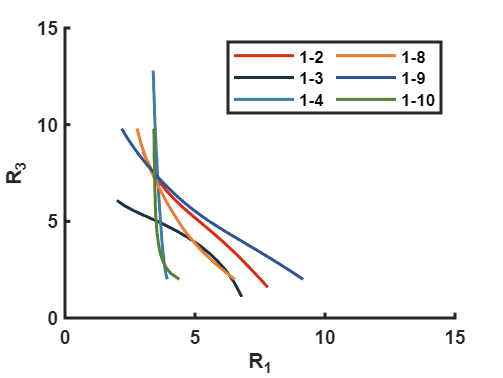

plot(x8,y8,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','1-10')




set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end



